# Unsupervised Day-to-Dusk Image Translation Using UNIT

This example shows how to translate images between daytime and dusk lighting conditions using an unsupervised image-to-image translation network (UNIT).

Domain translation is the task of transferring styles and characteristics from one image domain to another. This technique can be extended to other image-to-image learning operations, such as image enhancement, image colorization, defect generation, and medical image analysis.

UNIT [1] is a type of generative adversarial network (GAN) that consists of one generator network and two discriminator networks that you train simultaneously to maximize the overall performance. For more information about UNIT, see [Get Started with GANs for Image Synthesis and Analysis](docid:images_ug#mw_b8dc444c-09eb-4e9e-8f7d-99697ad42a0b).

## Data Set

Number of clear images: 618

Number of wet images: 1561

Specify `dataDir_*` as the desired location of the data. 

dataDir_clear = "C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_clear";
dataDir_wet = "C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet";
%
imgDir_clear = fullfile(dataDir_clear,"images");
imgDir_wet = fullfile(dataDir_wet,"images");

## Load Clear and Wet Data

source: Percentage of daytime images used for training:     263/497     ~=     53%     -->    number of test images day:     234/497

target:   Percentage of images at dusk used for training:     107/124     ~=     86%      -->    number of test images dusk:     17/124

This results in the following numbers for spray training and testing:

source: training clear:     328/618        -->     test clear:     290/618

target:   training wet:   1342/1561        -->     test wet:     219/1561

The CamVid image data set includes 497 images acquired in daytime and 124 images acquired at dusk. The performance of the trained UNIT network is limited because the number of CamVid training images is relatively small, which limits the performance of the trained network. Further, some images belong to an image sequence and therefore are correlated with other images in the data set. To minimize the impact of these limitations, this example manually partitions the data into training and test data sets in a way that maximizes the variability of the training data.

Create [`imageDatastore`](docid:matlab_ref#butueui-1) objects that manage the clear and wet images for training and testing.

imdsClearTrain = imageDatastore("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_clear\clear_train");
imdsWetTrain = imageDatastore("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\wet_train");

imdsClearTest = imageDatastore("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_clear\clear_test");
imdsWetTest = imageDatastore("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\wet_test");

Preview a training image from the day and dusk training data sets.

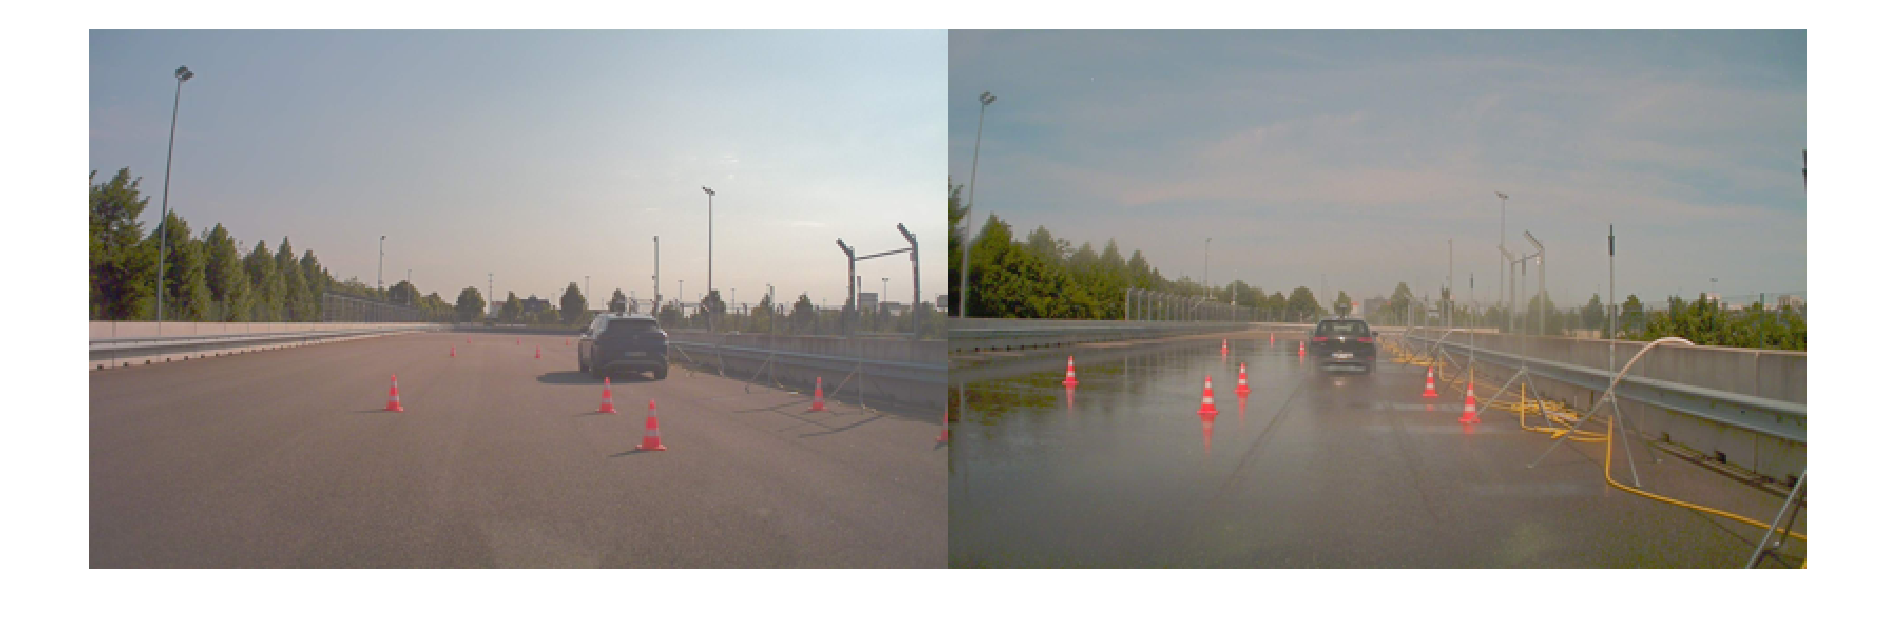

clear = preview(imdsClearTrain);
wet = preview(imdsWetTrain);
montage({clear,wet})

## Preprocess and Augment Training Data

Specify the image input size for the source and target images.

inputSize = [256,256,3];

Augment and preprocess the training data by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the helper function `augmentDataForDayToDusk`. This function is attached to the example as a supporting file.

The `augmentDataForDayToDusk` function performs these operations:

- Resize the image to the specified input size using bicubic interpolation. 

- Randomly flip the image in the horizontal direction.

- Scale the image to the range [-1, 1]. This range matches the range of the final [`tanhLayer`](docid:nnet_ref#mw_949dc76f-2d52-4e0c-905d-7f0a5728e27d) used in the generator.

imdsClearTrain = transform(imdsClearTrain, @(x)augmentDataForDayToDusk(x,inputSize));
imdsWetTrain = transform(imdsWetTrain, @(x)augmentDataForDayToDusk(x,inputSize));

## Create Generator Network

Create a UNIT generator network using the [`unitGenerator`](docid:images_ref#mw_8f0acbb9-58c2-431e-987f-69da93dda11a) function. The source and target encoder sections of the generator each consist of two downsampling blocks and five residual blocks. The encoder sections share two of the five residual blocks. Similarly, the source and target decoder sections of the generator each consist of two downsampling blocks and five residual blocks, and the decoder sections share two of the five residual blocks.

gen = unitGenerator(inputSize, NumResidualBlocks=5, NumSharedBlocks=2);

Visualize the generator network.

analyzeNetwork(gen)

## Create Discriminator Networks

Create two discriminator networks, one for each of the source and target domains, using the [`patchGANDiscriminator`](docid:images_ref#mw_dc465161-f2dd-411b-bc98-4ae7e5934055) function. Day is the source domain and dusk is the target domain.

discClear = patchGANDiscriminator(inputSize,NumDownsamplingBlocks=4,FilterSize=3, ...
    ConvolutionWeightsInitializer="narrow-normal",NormalizationLayer="none");
discWet = patchGANDiscriminator(inputSize,NumDownsamplingBlocks=4,FilterSize=3, ...
    ConvolutionWeightsInitializer="narrow-normal",NormalizationLayer="none");

Visualize the discriminator networks.

analyzeNetwork(discClear);
analyzeNetwork(discWet);

## Define Model Gradients and Loss Functions

The `modelGradientDisc` and `modelGradientGen` helper functions calculate the gradients and losses for the discriminators and generator, respectively. These functions are defined in the Supporting Functions section of this example.

The objective of each discriminator is to correctly distinguish between real images (1) and translated images (0) for images in its domain. Each discriminator has a single loss function. 

The objective of the generator is to generate translated images that the discriminators classify as real. The generator loss is a weighted sum of five types of losses: self-reconstruction loss, cycle consistency loss, hidden KL loss, cycle hidden KL loss, and adversarial loss.

Specify the weight factors for the various losses.

lossWeights.selfReconLossWeight = 10;
lossWeights.hiddenKLLossWeight = 0.01;
lossWeights.cycleConsisLossWeight = 10;
lossWeights.cycleHiddenKLLossWeight = 0.01;
lossWeights.advLossWeight = 1;
lossWeights.discLossWeight = 0.5;

## Specify Training Options

Specify the options for Adam optimization. Train the network for 35 epochs. Specify identical options for the generator and discriminator networks.

- Specify an equal learning rate of 0.0001.

- Initialize the trailing average gradient and trailing average gradiscDayAvgGradientdient-square decay rates with `[]`.

- Use a gradient decay factor of 0.5 and a squared gradient decay factor of 0.999.

- Use weight decay regularization with a factor of 0.0001.

- Use a mini-batch size of 1 for training.

learnRate = 0.0001;
gradDecay = 0.5;
sqGradDecay = 0.999;
weightDecay = 0.0001;

genAvgGradient = [];
genAvgGradientSq = [];

discClearAvgGradient = [];
discClearAvgGradientSq = [];

discWetAvgGradient = [];
discWetAvgGradientSq = [];

miniBatchSize = 1;
numEpochs = 35;

## Batch Training Data

Create a [`minibatchqueue`](docid:nnet_ref#mw_412afe49-5c0e-4f1b-8df7-b229f1b07eec) object that manages the mini-batching of observations in a custom training loop. The `minibatchqueue` object also casts data to a [`dlarray`](docid:nnet_ref#mw_bc7bf07e-0207-40d7-8568-5bdd002c6390) object that enables automatic differentiation in deep learning applications.

Specify the mini-batch data extraction format as "`SSCB"` (spatial, spatial, channel, batch). Set the `DispatchInBackground` name-value argument as the boolean returned by [`canUseGPU`](docid:matlab_ref#mw_9c1137a1-79ed-4efb-8234-814840e5e5a4). If a supported GPU is available for computation, then the `minibatchqueue` object preprocesses mini-batches in the background in a parallel pool during training.

mbqClearTrain = minibatchqueue(imdsClearTrain,MiniBatchSize=miniBatchSize, ...
    MiniBatchFormat="SSCB",DispatchInBackground=canUseGPU);
mbqWetTrain = minibatchqueue(imdsWetTrain,MiniBatchSize=miniBatchSize, ...
    MiniBatchFormat="SSCB",DispatchInBackground=canUseGPU);

## Train Network

By default, the example downloads a pretrained version of the UNIT generator for the CamVid data set. The pretrained network enables you to run the entire example without waiting for training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. Train the model in a custom training loop. For each iteration:

- Read the data for the current mini-batch using the [`next`](docid:nnet_ref#mw_20bf032b-172b-4668-8896-9017402c8b3c) function.

- Evaluate the model gradients using the [`dlfeval`](docid:nnet_ref#mw_bdc503ca-68b1-4790-815e-6277f7d1e62e) function and the `modelGradientDisc` and `modelGradientGen` helper functions.

- Update the network parameters using the [`adamupdate`](docid:nnet_ref#mw_1400a3cf-e891-44c4-81bf-b6aac542f3f1) function.

- Display the input and translated images for both the source and target domains after each epoch.

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For more information, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Training takes about 88 hours on an NVIDIA Titan RTX.

doTraining = true;  % false
if doTraining
    % Create a figure to show the results
    figure(Units="Normalized");
    for iPlot = 1:4
        ax(iPlot) = subplot(2,2,iPlot);
    end
    
    iteration = 0;

    % Loop over epochs
    for epoch = 1:numEpochs
        
        % Shuffle data every epoch
        reset(mbqClearTrain);
        shuffle(mbqClearTrain);
        reset(mbqWetTrain);
        shuffle(mbqWetTrain);
        
        % Run the loop until all the images in the mini-batch queue 
        % mbqClearTrain are processed
        while hasdata(mbqClearTrain)
            iteration = iteration + 1;
            
            % Read data from the day domain
            imDay = next(mbqClearTrain); 
             
            % Read data from the dusk domain
            if hasdata(mbqWetTrain) == 0
                reset(mbqWetTrain);
                shuffle(mbqWetTrain);
            end
            imDusk = next(mbqWetTrain);
    
            % Calculate discriminator gradients and losses
            [discDayGrads,discDuskGrads,discDayLoss,disDuskLoss] = dlfeval( ...
                @modelGradientDisc,gen,discClear,discWet,imDay,imDusk, ...
                lossWeights.discLossWeight);
            
            % Apply weight decay regularization on day discriminator gradients
            discDayGrads = dlupdate(@(g,w) g+weightDecay*w, ...
                discDayGrads,discClear.Learnables);
            
            % Update parameters of day discriminator
            [discClear,discClearAvgGradient,discClearAvgGradientSq] = adamupdate( ...
                discClear,discDayGrads,discClearAvgGradient,discClearAvgGradientSq, ...
                iteration,learnRate,gradDecay,sqGradDecay);  
            
            % Apply weight decay regularization on dusk discriminator gradients
            discDuskGrads = dlupdate(@(g,w) g+weightDecay*w, ...
                discDuskGrads,discWet.Learnables);
            
            % Update parameters of dusk discriminator
            [discWet,discWetAvgGradient,discWetAvgGradientSq] = adamupdate( ...
                discWet,discDuskGrads,discWetAvgGradient,discWetAvgGradientSq, ...
                iteration,learnRate,gradDecay,sqGradDecay);
            
            % Calculate generator gradient and loss
            [genGrad,genLoss,images] = dlfeval( ...
                @modelGradientGen,gen,discClear,discWet,imDay,imDusk,lossWeights);
            
            % Apply weight decay regularization on generator gradients
            genGrad = dlupdate(@(g,w) g+weightDecay*w,genGrad,gen.Learnables);
            
            % Update parameters of generator
            [gen,genAvgGradient,genAvgGradientSq] = adamupdate( ...
                gen,genGrad,genAvgGradient,genAvgGradientSq, ...
                iteration,learnRate,gradDecay,sqGradDecay);
        end
        
        % Display the results
        updateTrainingPlotDayToDusk(ax,images{:});
    end
    
    % Save the trained network
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save(fullfile(dataDir,"trainedDayDuskUNITGeneratorNet-"+modelDateTime+".mat"),"gen");
    
else    
    net_url = "https://ssd.mathworks.com/supportfiles/"+ ...
        "vision/data/trainedDayDuskUNITGeneratorNet.zip";
    downloadTrainedNetwork(net_url,dataDir);
    load(fullfile(dataDir,"trainedDayDuskUNITGeneratorNet.mat"));
end

## Evaluate Source-to-Target Translation

Source-to-target image translation uses the UNIT generator to generate an image in the target domain (dusk) from an image in the source domain (day).

Read an image from the datastore of day test images.

idxToTest = 1;
clearTestImage = readimage(imdsClearTest,idxToTest);

Convert the image to data type `single` and normalize the image to the range [-1, 1].

clearTestImage = im2single(clearTestImage);
clearTestImage = (clearTestImage-0.5)/0.5;

Create a `dlarray` object that inputs data to the generator. If a supported GPU is available for computation, then perform inference on a GPU by converting the data to a `gpuArray` object.

dlClearImage = dlarray(clearTestImage,"SSCB");    
if canUseGPU
    dlClearImage = gpuArray(dlClearImage);
end

Translate the input day image to the dusk domain using the [`unitPredict`](docid:images_ref#mw_84750717-5a6e-4aec-9583-14684935730b) function.

dlClearToWetImage = unitPredict(gen,dlClearImage);
clearToWetImage = extractdata(gather(dlClearToWetImage));

The final layer of the generator network produces activations in the range [-1, 1]. For display, rescale the activations to the range [0, 1]. Also, rescale the input day image before display.

clearToWetImage = rescale(clearToWetImage);
clearTestImage = rescale(clearTestImage);

Display the input day image and its translated dusk version in a montage.

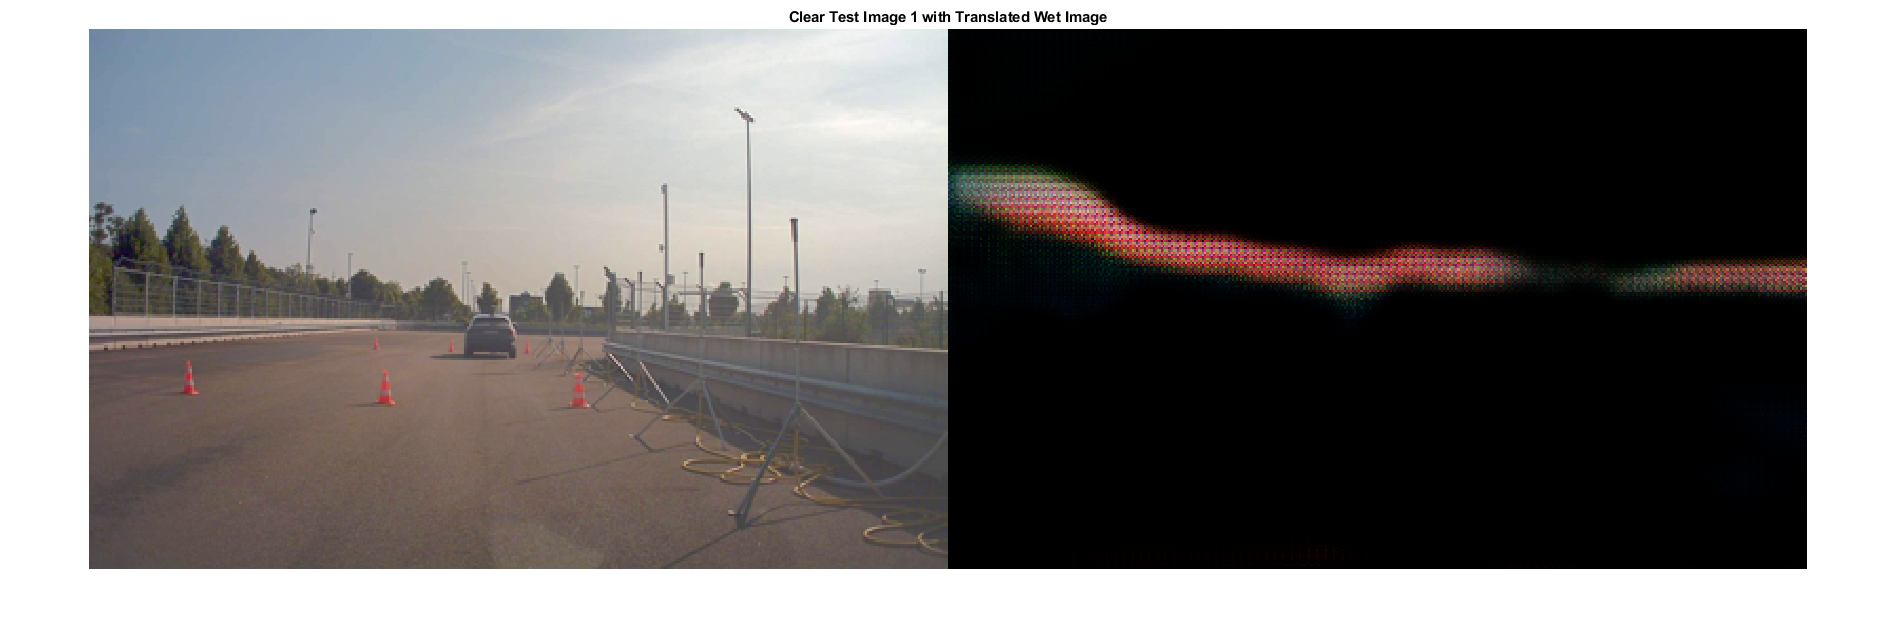

figure
montage({clearTestImage clearToWetImage})
title("Clear Test Image "+num2str(idxToTest)+" with Translated Wet Image")

## Evaluate Target-to-Source Translation

Target-to-source image translation uses the UNIT generator to generate an image in the source domain (day) from an image in the target domain (dusk).

Read an image from the datastore of dusk test images.

idxToTest = 1;
wetTestImage = readimage(imdsWetTest,idxToTest);

Convert the image to data type `single` and normalize the image to the range [-1, 1].

wetTestImage = im2single(wetTestImage);
wetTestImage = (wetTestImage-0.5)/0.5;

Create a `dlarray` object that inputs data to the generator. If a supported GPU is available for computation, then perform inference on a GPU by converting the data to a `gpuArray` object.

dlWetImage = dlarray(wetTestImage,"SSCB");    
if canUseGPU
    dlWetImage = gpuArray(dlWetImage);
end

Translate the input dusk image to the day domain using the [`unitPredict`](docid:images_ref#mw_84750717-5a6e-4aec-9583-14684935730b) function.

dlWetToClearImage = unitPredict(gen,dlWetImage,OutputType="TargetToSource");
WetToClearImage = extractdata(gather(dlWetToClearImage));

For display, rescale the activations to the range [0, 1]. Also, rescale the input dusk image before display.

WetToClearImage = rescale(WetToClearImage);
wetTestImage = rescale(wetTestImage);

Display the input dusk image and its translated day version in a montage.

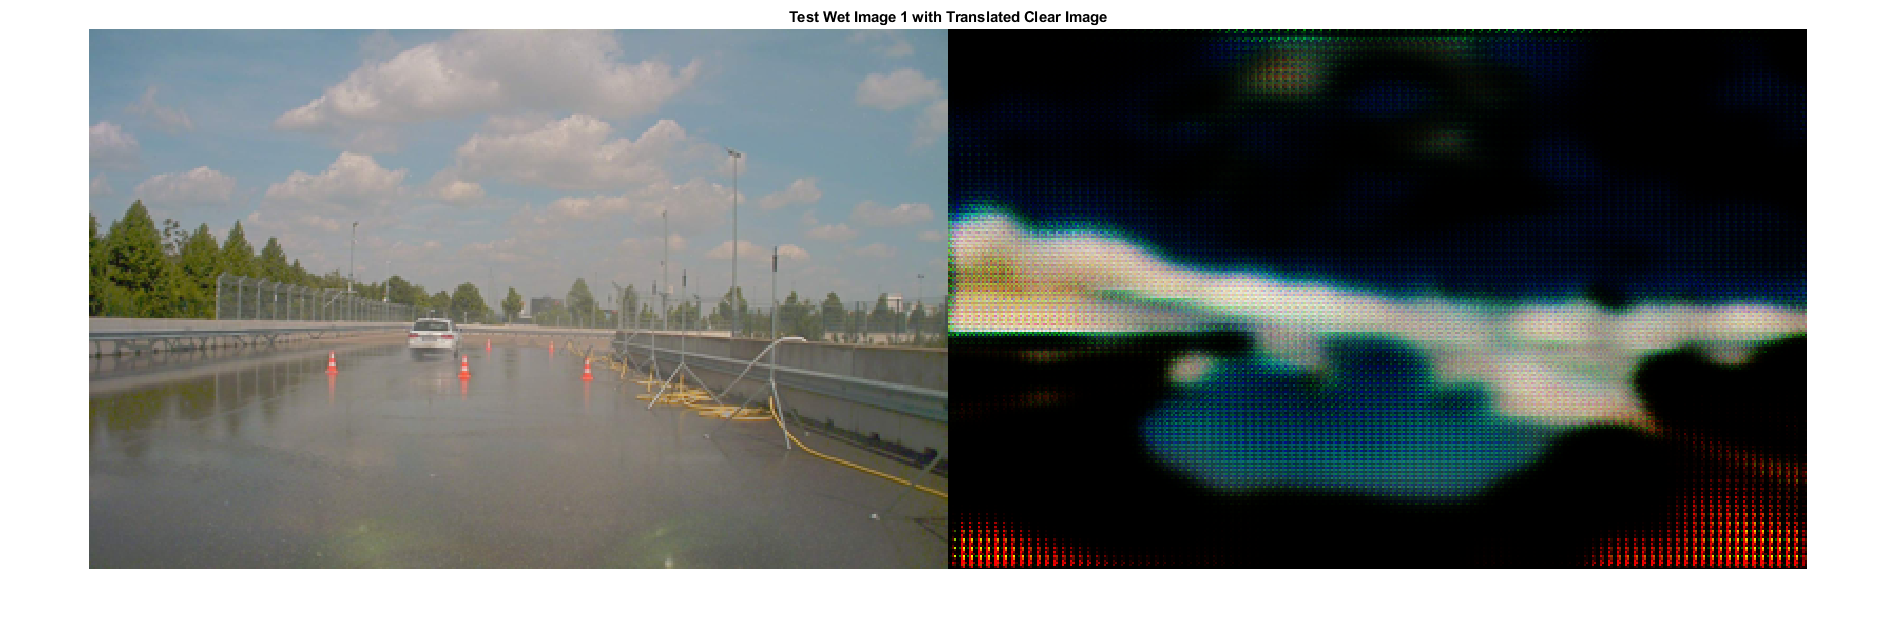

montage({wetTestImage WetToClearImage})
title("Test Wet Image "+num2str(idxToTest)+" with Translated Clear Image")

## Supporting Functions

### **Model Gradients Functions**

The `modelGradientDisc` helper function calculates the gradients and loss for the two discriminators. 

function [discAGrads,discBGrads,discALoss,discBLoss] = modelGradientDisc(gen, ...
    discA,discB,ImageA,ImageB,discLossWeight)

    [~,fakeA,fakeB,~] = forward(gen,ImageA,ImageB);
    
    % Calculate loss of the discriminator for X_A
    outA = forward(discA,ImageA); 
    outfA = forward(discA,fakeA);
    discALoss = discLossWeight*computeDiscLoss(outA,outfA);
    
    % Update parameters of the discriminator for X
    discAGrads = dlgradient(discALoss,discA.Learnables); 
    
    % Calculate loss of the discriminator for X_B
    outB = forward(discB,ImageB); 
    outfB = forward(discB,fakeB);
    discBLoss = discLossWeight*computeDiscLoss(outB,outfB);
    
    % Update parameters of the discriminator for Y
    discBGrads = dlgradient(discBLoss,discB.Learnables);
    
    % Convert the data type from dlarray to single
    discALoss = extractdata(discALoss);
    discBLoss = extractdata(discBLoss);
end

The `modelGradientGen` helper function calculates the gradients and loss for the generator.

function [genGrad,genLoss,images] = modelGradientGen(gen, ...
    discA,discB,ImageA,ImageB,lossWeights)
    
    [ImageAA,ImageBA,ImageAB,ImageBB] = forward(gen,ImageA,ImageB);
    hidden = forward(gen,ImageA,ImageB,Outputs="encoderSharedBlock");
    
    [~,ImageABA,ImageBAB,~] = forward(gen,ImageBA,ImageAB);
    cycle_hidden = forward(gen,ImageBA,ImageAB,Outputs="encoderSharedBlock");
    
    % Calculate different losses
    selfReconLoss = computeReconLoss(ImageA,ImageAA) + computeReconLoss(ImageB,ImageBB);
    hiddenKLLoss = computeKLLoss(hidden);
    cycleReconLoss = computeReconLoss(ImageA,ImageABA) + computeReconLoss(ImageB,ImageBAB);
    cycleHiddenKLLoss = computeKLLoss(cycle_hidden);
    
    outA = forward(discA,ImageBA);
    outB = forward(discB,ImageAB);
    advLoss = computeAdvLoss(outA) + computeAdvLoss(outB);
    
    % Calculate the total loss of generator as a weighted sum of five losses
    genTotalLoss = ...
        selfReconLoss*lossWeights.selfReconLossWeight + ...
        hiddenKLLoss*lossWeights.hiddenKLLossWeight + ...
        cycleReconLoss*lossWeights.cycleConsisLossWeight + ...
        cycleHiddenKLLoss*lossWeights.cycleHiddenKLLossWeight + ...
        advLoss*lossWeights.advLossWeight;
    
    % Update the parameters of generator
    genGrad = dlgradient(genTotalLoss,gen.Learnables); 
    
    % Convert the data type from dlarray to single
    genLoss = extractdata(genTotalLoss);
    images = {ImageA,ImageAB,ImageB,ImageBA};
end

### Loss Functions

The `computeDiscLoss` helper function calculates the discriminator loss. Each discriminator loss is a sum of two components:

- The squared difference between a vector of ones and the predictions of the discriminator on real images, $Y_{\textrm{real}}$

- The squared difference between a vector of zeros and the predictions of the discriminator on generated images, ${\hat{Y} }_{\textrm{translated}}$

 
$$\textrm{discriminatorLoss}={\left(1-Y_{\textrm{real}} \right)}^2 +{\left(0-{\hat{Y} }_{\textrm{translated}} \right)}^2$$


function discLoss = computeDiscLoss(Yreal,Ytranslated)
    discLoss = mean(((1-Yreal).^2),"all") + ...
               mean(((0-Ytranslated).^2),"all");
end

The `computeAdvLoss` helper function calculates the adversarial loss for the generator. Adversarial loss is the squared difference between a vector of ones and the discriminator predictions on the translated image.


$$\textrm{adversarialLoss}={\left(1-{\hat{Y} }_{\textrm{translated}} \right)}^2$$


function advLoss = computeAdvLoss(Ytranslated)
    advLoss = mean(((Ytranslated-1).^2),"all");
end

The `computeReconLoss` helper function calculates the self-reconstruction loss and cycle-consistency loss for the generator. Self-reconstruction loss is the $L^1$ distance between the input images and their self-reconstructed versions. Cycle-consistency loss is the $L^1$ distance between the input images and their cycle-reconstructed versions.


$$\textrm{selfReconstructionLoss}={\left\|\left(Y_{\textrm{real}} -Y_{\textrm{self}-\textrm{reconstructed}} \right)\right\|}_1$$



$$\textrm{cycleConsistencyLoss}={\left\|\left(Y_{\textrm{real}} -Y_{\textrm{cycle}-\textrm{reconstructed}} \right)\right\|}_1$$


function reconLoss = computeReconLoss(Yreal,Yrecon)
    reconLoss = mean(abs(Yreal-Yrecon),"all");
end

The `computeKLLoss` helper function calculates the hidden KL loss and cycle-hidden KL loss for the generator. Hidden KL loss is the squared difference between a vector of zeros and the `encoderSharedBlock` activation for the self-reconstruction stream. Cycle-hidden KL loss is the squared difference between a vector of zeros and the `encoderSharedBlock` activation for the cycle-reconstruction stream.


$$\textrm{hiddenKLLoss}={\left(0-Y_{\textrm{encoderSharedBlockActivation}} \right)}^2$$



$$\textrm{cycleHiddenKLLoss}={\left(0-Y_{\textrm{encoderSharedBlockActivation}} \right)}^2$$


function klLoss = computeKLLoss(hidden)
    klLoss = mean(abs(hidden.^2),"all");
end

## References

[1] Liu, Ming-Yu, Thomas Breuel, and Jan Kautz, "Unsupervised image-to-image translation networks". In *Advances in Neural Information Processing Systems, *2017. [https://arxiv.org/abs/1703.00848](https://arxiv.org/abs/1703.00848).

[2] Brostow, Gabriel J., Julien Fauqueur, and Roberto Cipolla. "Semantic Object Classes in Video: A High-Definition Ground Truth Database." *Pattern Recognition Letters*. Vol. 30, Issue 2, 2009, pp 88-97.

*Copyright 2020 The MathWorks, Inc.*